# create timetable from gdt file

## loading the file and extracting the table 

%gdt
options = detectImportOptions('ANON_19810211.GDT', 'FileType','text');
T = readtable('ANON_19810211.GDT', options); % can't use this for gdt file.

%edf
edfFile1 = edfread('ANONCapno edf export -1.edf');
edfFile2 = edfread('HT capno.edf');
edfFile3 = edfread('GD capno.edf');
edfFile4 = edfread('WP capno.edf');

## removing NaN values

%gdt
T.PaCO2(isnan(T.PaCO2)) = 0; %replace Nan values with 0 so they dont get removed in next step
gdtfile = T(~any(ismissing(T),2),:);%remove all rows that have missing value or NaN. now we only have the table remaining.


## samplingTime and samplePeriod

%gdt
gdtSamplingTime = seconds(duration(gdtfile.Time, 'InputFormat','mm:ss'));%convert to duration
gdtSamplePeriod = round(mean(diff(gdtSamplingTime)))%difference between the samples and we take the mean of that

gdtSamplePeriod = 10

gdtSampleRate = 1/gdtSampleperiod

gdtSampleRate = 0.1000

% edf
edfSamplingTime = seconds(duration(edfFile1.("Record Time")));
edfSamplePeriod = round(mean(diff(edfSamplingTime)))

edfSamplePeriod = 1

## convert to timetables

gdtfile.Time=[];%remove Time collumn
Time=transpose(seconds(0:gdtSamplePeriod:(height(gdtfile)-1)*gdtSamplePeriod ))%create new time collumn

Time = 96×1 duration array
     0 sec
    10 sec
    20 sec
    30 sec
    40 sec
    50 sec
    60 sec
    70 sec
    80 sec
    90 sec
   100 sec
   110 sec
   120 sec
   130 sec
   140 sec
   150 sec
   160 sec
   170 sec
   180 sec
   190 sec
   200 sec
   210 sec
   220 sec
   230 sec
   240 sec
   250 sec
   260 sec
   270 sec
   280 sec
   290 sec


gdtTimeTable=table2timetable(gdtfile,'RowTimes',Time);

## plot gdt

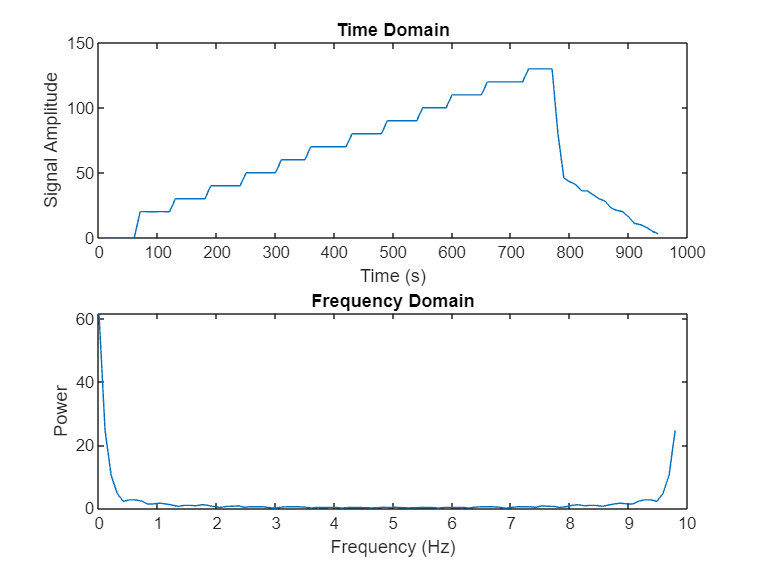

y = gdtfile.Load; %the signal you want to convert
n = length(y);
f = (0:n-1)*(gdtSampleperiod/n); % frequency range
Y = fft(y)/n; % Fourier transform
power = abs(Y); % power spectrum
figure
subplot(2,1,1)
plot(gdtSamplingTime, y)
xlabel('Time (s)')
ylabel('Signal Amplitude')
title('Time Domain')

subplot(2,1,2)
plot(f,power)
xlabel('Frequency (Hz)')
ylabel('Power')
title('Frequency Domain')

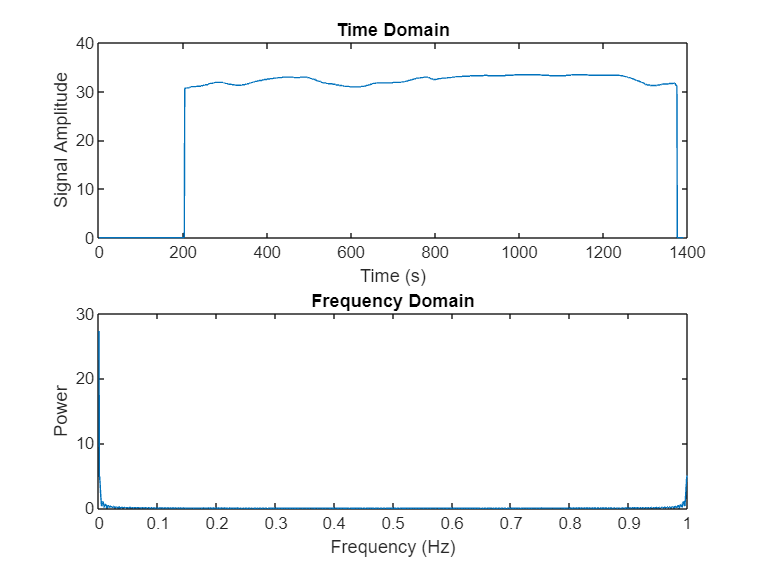

%% plot edf
y = edfFile1.PCO2_DC; %the signal you want to convert
n = length(y);
f = (0:n-1)*(edfSamplePeriod/n); % frequency range
Y = fft(y)/n; % Fourier transform
power = abs(Y); % power spectrum

figure
subplot(2,1,1)
plot(edfSamplingTime, y)
xlabel('Time (s)')
ylabel('Signal Amplitude')
title('Time Domain')

subplot(2,1,2)
plot(f,power)
xlabel('Frequency (Hz)')
ylabel('Power')
title('Frequency Domain')

temp = power;%for testing